clc;
clearvars;

**Input variables:**

W0 = 100;                               % Mass flow                               (kg/s)
R = 287.05;                             % Gas constant                            (J/kgK)
IntakeP_loss = 0;                       % Intake pressure loss                    (%)
ExhaustP_loss = 0;                      % Exhaust pressure loss                   (kPa)
JetpipeP_loss = 0;                      % Jet pipe pressure loss                  (%)
CD = 1;                                 % Coefficient of discharge                (%)
CX = 1;                                 % Coefficient of thrust                   (%)
Mech_Eff = 0.86;                        % Mechanical efficiency                   (%)
V0 = 250;                               % Airspeed                                (m/s)

**Input height: calculates temperature and pressure**

h = linspace(0,20000,100);

Pb = 101.325;
Tb = 288.2;
hb = 0;
Lb = 0.0065;
g = 9.80665;
Mol = 0.0289644;
R1 = 8.3144598;
P0 = Pb * ((Tb - (h - hb) * Lb)/Tb).^((g * Mol)/(R1 * Lb));

T0 = Tb - (h * Lb);

**Compressor:**

y_c = 1.4;                              % Heat capacity ratio compressor          (-)
CompressorIsent_Eff = 0.9;              % Compressor isentropic efficiency        (%)
ETAP2 = 0;                              % Compressor polytopic efficiency         (%)
CP_compressor = 1.005;                  % Specific heat compressor                (kJ/kg)
P3Q2 = 8;                               % Pressure ratio compressor               (-)
CompressorP_loss = 0.0;                 % Compressor pressure loss                (%

**Combustor:**

CombustionP_loss = 0.05;                % Combustion pressure loss                (kPa)
CombustionIsent_Eff = 0.95;             % Combustion efficiency                   (%)

**Turbine:**

y_t = 4/3;                              % Heat capcity ratio turbine              (-)
TurbineIsent_Eff = 0.86;                % Turbine isentropic efficiency           (%)
TurbinePoly_Eff = 0;                    % Turbine polytropical eff.               (%)
CP_turbine = 1.150;                     % Specific heat turbine                   (kJ/kg)

**Temperatures:**

T4 = 1800;                              % Temperature after combustion            (K)

**Bleed:**

Bleed1 = 0.0;                           % Bleed air from compressor to outlet     (%)
Bleed2 = 0.0;                           % Bleed air from compressor to LPT        (%)
Bleed3 = 0.0;                           % Bleed air from compressor to HPT        (%)
Bleed4 = 0.0;                           % Bleed air to first LPT nozzle           (%)
Bleed5 = 0.0;                           % Bleed air to second LPT nozzle          (%)

**Fuel:**

LHV = 43*10^6;                          % Calorific value fuel                  (kJ/kg)

**Stations: **

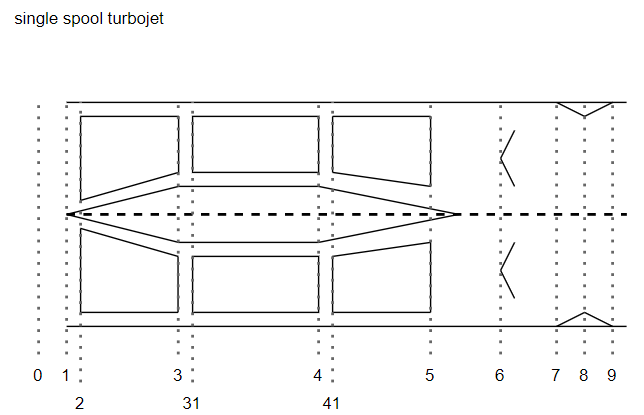

**Station 0: atmosperic calculations**

T0;
P0;
W0;

**Station 1: Intake**

T1 = T0;
P1 = P0;
W1 = W0;

**Station 2: Compressor inlet**

T2 = T1;
P2 = P1 * (1 - IntakeP_loss); 
W2 = W1;

**Station 3 :Compressor calculations: **

T3 = (T2/CompressorIsent_Eff) * (P3Q2^((y_c-1)/y_c)-1) + T2;
P3 = P3Q2 * P2;
W3 = W2 - (W0 * Bleed1) - (W0 * CompressorP_loss);                                                             
 
Tbleed = (T3 + T1)/2;
PW3 = W0 * (CP_compressor) * (T3 - T1)+ ((Bleed1+CompressorP_loss)*W0) * CP_compressor * (Tbleed - T0);                               % No Tbleed

**Station 31: Combuster inlet **

T31 = T3;
P31 = P3;
W31 = W3 - (W0 * Bleed2) - (W0 * Bleed3);

**Station 4: Combustor outlet: **

P4 = P31 * (1 - CombustionP_loss);
T4;
FAR1 = 0.10118 + 2.00376E-05.* (700 - T31);
FAR2 = 3.7078E-03 - 5.2368E-06.* (700 - T31) - 5.2632E-06 * T4;
FAR3 = 8.889E-08 * abs(T4 - 950);
FAR = (FAR1 - sqrt(FAR1.^2 + FAR2) - FAR3)/CombustionIsent_Eff;
WF = FAR * W31;                 
W4 = W31 + WF + (W0 * Bleed3);

**Station 41: Turbine inlet calculations**

W41 = W4 + (W0*Bleed4);
T41 = ((W41 * CP_turbine * T4)-((Bleed3 * W0) * CP_compressor * T31))./(W41 * CP_turbine);
P41 = P4;

**Station 5: Turbine outlet calculations:**

WC = W2 * CP_compressor * (T31 - T2);
T5 = T41 - (WC./(W4 * CP_turbine));
Expansion_ratio = nthroot((1-(T41-T5)./(TurbineIsent_Eff*T41)),(-1/4));
P5 = P41./Expansion_ratio;
W5 = W41 + (Bleed5 * W0) + (Bleed1 * W0);

**Station 6: Afterburner calculations **

T6 = T5;
P6 = P5;
W6 = W5;

**Station 7: Propelling nozzle inlet**

T7 = T6;
P7 = P6 * (1-JetpipeP_loss);
W7 = W6;

**Station 8: Propelling nozzle throat:**

T8 = T6;                                                
P8 = P6;
W8 = W6;

Ps = P6./(1 + (y_c - 1)/2).^(y_c/(y_c-1));
Ts = T6./(1 + (y_c - 1)/2);
VN = sqrt(y_t * R * Ts);                                 % Nett velocity                                             

rho = (Ps.*1000)./(Ts.*R);
ANeffective = W0./(VN.* rho);   

**Sation 9: Exhaust calculations: **

P9 = P0 * 1.02;
T9 = T5-(TurbineIsent_Eff.*T5).*(1-(1./(P5./P9)).^0.25);
W9 = W5;
UW = (T8-T9).*CP_turbine.*W9;

**Final calculations:**

Fn = (W0 + WF).* VN + ANeffective.* (Ps - P1).* 1000;   % Thrust
SFN = Fn/W0;                                            % Specific thrust
SFC = (WF./Fn).*1000000;                                % Specific fuel consumption                 
SPW = Fn/W0;                                            % Specific power 
ETATH1 = 100.*(3600./(SFC.*(LHV/10^5)));                % Thermal efficiency
ETATH2 = 100*(UW./((T4-T3)*W0*CP_turbine));             % Thermal efficiency
ETAPROP = 100*((2.*V0)./(V0+VN));                       % Propulsive efficiency
TOTEFF = (ETATH2.*ETAPROP)./100;                        % Total efficiency

**Plots:**

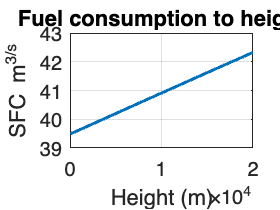

s1 = plot (h, SFC,LineWidth=1.5);
title('Fuel consumption to height');
xlabel('Height (m)');
ylabel('SFC m^3/s');
grid on;

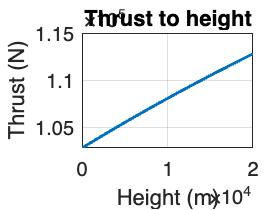


s2 = plot (h, Fn,LineWidth=1.5);
title('Thrust to height');
xlabel('Height (m)');
ylabel('Thrust (N)');
grid on;

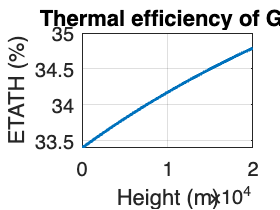


s3 = plot (h, ETATH2,LineWidth=1.5);
title('Thermal efficiency of GT');
xlabel('Height (m)');
ylabel('ETATH (%)');
grid on;

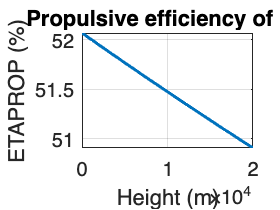


s4 = plot(h, ETAPROP,LineWidth=1.5);
title('Propulsive efficiency of GT');
xlabel('Height (m)');
ylabel('ETAPROP (%)');
grid on;

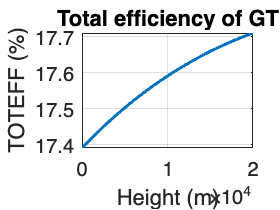


s5 = plot(h,TOTEFF,LineWidth=1.5);
title('Total efficiency of GT');
xlabel('Height (m)');
ylabel('TOTEFF (%)');
grid on;

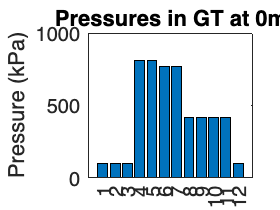


Gx1 = 1:12;
Gy1 = [P0(1,1),P1(1,1),P2(1,1),P3(1,1),P31(1,1),P4(1,1),P41(1,1),P5(1,1),P6(1,1),P7(1,1),P8(1,1),P9(1,1)];
g1 = bar(Gx1,Gy1);
title('Pressures in GT at 0m');
ylabel('Pressure (kPa)');

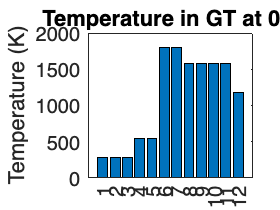


Gx2 = 1:12;
Gy2 = [T0(1,1),T1(1,1),T2(1,1),T3(1,1),T31(1,1),T4(1,1),T41(1,1),T5(1,1),T6(1,1),T7(1,1),T8(1,1),T9(1,1)];
g2 = bar(Gx2,Gy2);
title('Temperature in GT at 0m');
ylabel('Temperature (K)');

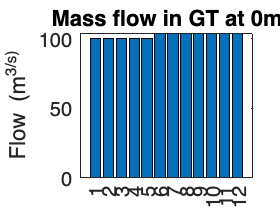


Gx3 = 1:12;
Gy3 = [W0(1,1),W1(1,1),W2(1,1),W3(1,1),W31(1,1),W4(1,1),W41(1,1),W5(1,1),W6(1,1),W7(1,1),W8(1,1),W9(1,1)];
g3 = bar(Gx3,Gy3);
title('Mass flow in GT at 0m');
ylabel('Flow (m^3/s)');

Un used formulas:

% Q = 1000 * sqrt( 2 * y_t/((y_t-1) * R) * ((1+0.2*1^2)^3.5)^(-2/y_t) * (1 - ((1+0.2*1^2)^3.5)^ ((1 - y_t)/y_t)))
% Q = W31 * CP_turbine * (T4 - T31);
% DT = T4 - T1;
% DH = DT * W31 * CP_turbine;
% P4_5 = P3_5* (1- (1-(T3_5/T3))/ETHA_turb).^(y_t/(y_t- 1));
% P4_5 = PAMB/(1-ExhaustP_loss);
% E415 = (1 - P415Q416^(- ((y_t-1)/y_t) * TurbineIsent_Eff))/(1 - P415Q416^(-(y_t-1)/y_t));
% T416 = E415 * T4 * (1 - P415Q416^(-((y_t-1)/y_t)));
% PW415 = W415 * CP_turbine * (T4 - T416);                
% WRTP4 = W3_5 * sqrt(T3_5)/P3_5;
% WRTP41 = W3_5 * sqrt(T41)/P3_5;
% T5 = T4_5 - (PW2/(W3_5 * CP_turbine))
% ANeffective = (W6 * sqrt(T5))/(Q * P6);
% ANgeometric = ANeffective/CD;
% FD = 100 * V1;                                          % Momentum drag
% FN = FG * CX - FD;                                    % Net thrust
% PW = PW415 - PW2/Mech_Eff 
